## ASTR363 Problem 4 matlab 

clc
close all
clear all

% Reading the data files as matrices
file = readmatrix("problem4.xlsx");
file(isnan(file)) = 0;

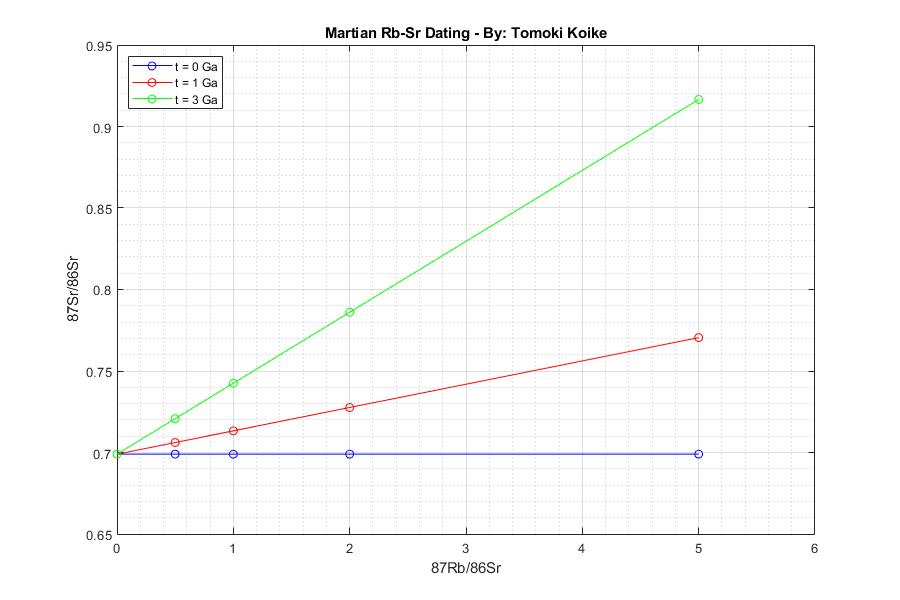


x = file(1:5,1);  % Getting the x-values 87Rb/86Sr
y1 = file(1:5,3);  % Getting the y-values 87Sr/86Sr for t=0 Ga
y2 = file(8:12,3);  % Getting the y-values 87Sr/86Sr for t=1 Ga
y3 = file(15:19,3);  % Getting the y-values 87Sr/86Sr for t=3 Ga

% Plotting 
figure('Renderer','painters','Position',[10 10 900 600])
plot(x,y1,'-ob');
title('Martian Rb-Sr Dating - By: Tomoki Koike')
xlabel('87Rb/86Sr')
ylabel('87Sr/86Sr')
hold on
plot(x,y2,'-or')
plot(x,y3,'-og')
hold off
grid on
grid minor
box on
xlim([0 6])
legend('t = 0 Ga', 't = 1 Ga', 't = 3 Ga', 'Location', 'northwest')